# **[2024년 1학기 디지털제어 MATLAB/Simulink 예제] Ch. 6-a. 폐루프 샘플 데이터 시스템의 시스템 응답**

- 본 파일은 2024년 1학기 개설된 서울시립대학교 전자전기컴퓨터공학부 **디지털제어** 교과목 수업의 보조 자료로 활용하기 위해 제작되었습니다.

- **작성자** : 서울시립대학교 전자전기컴퓨터공학부 박경훈 교수(gyunghoon.park@uos.ac.kr), 김준수 박사과정생

- **교과목 github 페이지 **: [https://github.com/CDSL-UoS/Course_Digital-Control_2024](https://github.com/CDSL-UoS/Course_Digital-Control_2024) 

- **교과목 notion 페이지** : [https://cdsl-uos-wiki.notion.site/2024-1-40067-01-f2be00650e8f4a3db78b7f464b94be14?pvs=4](https://cdsl-uos-wiki.notion.site/2024-1-40067-01-f2be00650e8f4a3db78b7f464b94be14?pvs=4) 

- **참고사항** : 2023b version 이상의 MATLAB/Simulink 환경에서 구동을 권장합니다. (2023a 이하 version 사용 시 Simulink 파일 등이 원활히 작동되지 않을 수 있습니다.)

아래 예제를 실행하기에 앞서, 다음 코드를 실행하여 작업 공간 등을 초기화합시다.

clc; clear all; close all;      % Initialization

### Topic 1 : 연속 시간 폐루프 시스템과 샘플 데이터 시스템의 응답 비교

이번 파일에서는 Chapter 5와 동일한 예제를 통해 폐루프 샘플 데이터 시스템의 시스템 응답을 학습합니다. 

특히 Topic 1에서는 연속 시간 폐루프 시스템과 샘플 데이터 시스템의 시간 영역에서의 동특성 차이에 대해 이해해보고자 합니다.

먼저 연속 시간 플랜트 $G_p(s)=\frac{1}{s+1}$와 연속 시간 제어기 $C(s)=\frac{1}{s}$로 구현된 연속 시간 폐루프 시스템을 생각합시다.

num_Gp_tf = [1];
den_Gp_tf = [1 1];
Gp_tf = tf(num_Gp_tf, den_Gp_tf);

num_C_tf = [1];
den_C_tf = [1 0];
C_tf = tf(num_C_tf, den_C_tf);

T_tf = (Gp_tf*C_tf)/(1 + Gp_tf*C_tf);
T_tf = minreal(T_tf);

여기서 어떤 이산화 방법을 통해 이산 시간 제어기 $C^d(z)$를 도출할지에 따라 결과가 상이할 수 있기 때문에 약간의 주의가 필요합니다.

지금의 예제는 단순하기 때문에, 큰 고민 없이 전방 차분법(forward difference method)를 통해 제어기를 변환하도록 합시다. 즉, 


$$C^d(z) = C(s)\bigg|_{s=\frac{z-1}{T}}=\frac{T}{z-1}$$


이제 위의 제어기를 

T = 0.2;
Gd_tf = c2d(Gp_tf, T, 'zoh');

num_Cd_tf = T;
den_Cd_tf = [1 -1];
Cd_tf = tf(num_Cd_tf, den_Cd_tf, T);

Td_tf = (Gd_tf*Cd_tf)/(1+Gd_tf*Cd_tf);
Td_tf = minreal(Td_tf);

MATLAB에서 제공하는 step 함수를 이용하여 간단하게 시뮬레이션해보면 다음 결과를 얻습니다.

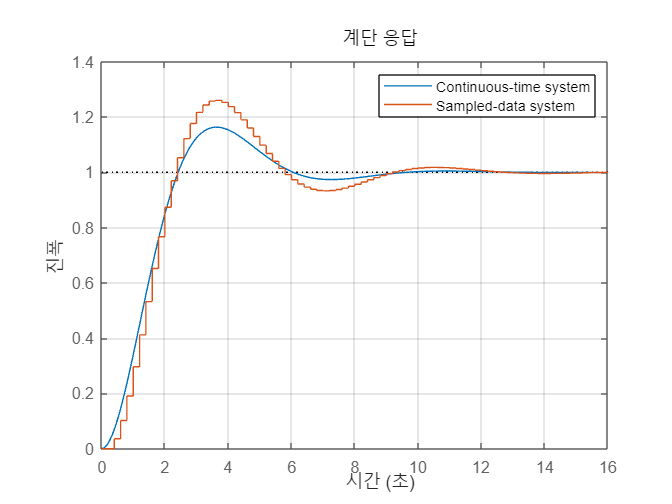

figure();
step(T_tf);
hold on;
step(Td_tf);
legend('Continuous-time system','Sampled-data system');
grid on;

지금의 예제에서는 샘플 데이터 시스템의 overshoot이 더 크고 settling time도 더 길기 때문에 제어 성능이 떨어지는 것으로 보여집니다. 

이는 샘플 데이터 시스템을 구성하는 과정에서 샘플러와 영차 홀드라고 하는 컴포넌트가 사용됨에 따른 추가적인 지연(delay)이 발생하였고, 제어기 역시 이산화됨에 따라 연속 시간 제어기를 정확히 구현해내지 못했기 때문으로 이해할 수 있습니다. 

한편 샘플링 주기를 조정하면 위의 현상이 개선될 수 있는데, 이를 확인하기 위해 3가지 샘플링 주기에 대한 계단 응답을 하나의 그림으로 그려봅시다.

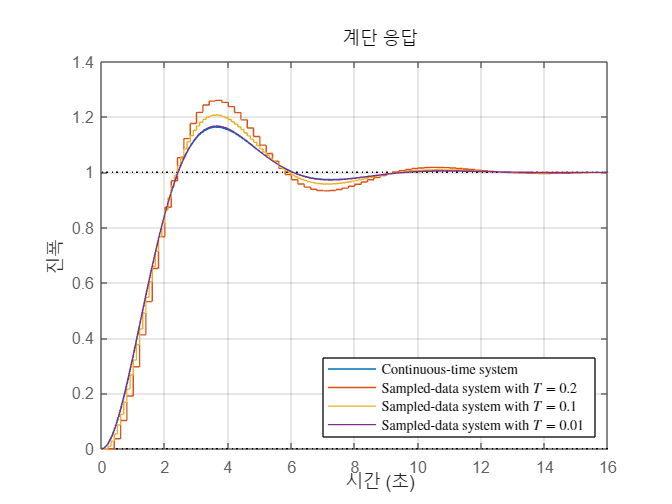

list_T = {0.2, 0.1, 0.01};
list_Td_tf = cell(3,1);

for idx = 1:3
    T = list_T{idx};
    Gd_tf = c2d(Gp_tf, T, 'zoh');
    num_Cd_tf = T;
    den_Cd_tf = [1 -1];
    Cd_tf = tf(num_Cd_tf, den_Cd_tf, T);
    Td_tf = (Gd_tf*Cd_tf)/(1+Gd_tf*Cd_tf);
    list_Td_tf{idx} = minreal(Td_tf);
end

figure();
step(T_tf);
for idx = 1:3
    hold on;
    step(list_Td_tf{idx});
end
legend('Continuous-time system','Sampled-data system with $T=0.2$', 'Sampled-data system with $T=0.1$', 'Sampled-data system with $T=0.01$','Interpreter','latex','Location','southeast');
grid on;

(그림 상에서 연속 시간 시스템의 응답에 해당하는 파란색 실선과, $T=0.01$인 경우의 샘플 데이터 시스템의 응답에 해당하는 보라색 실선이 거의 겹쳐보임에 유념합시다.)

그림에서 확인할 수 있듯, 샘플링 주기 $T$를 충분히 작게 하면 샘플 데이터 시스템이 연속 시간 시스템과 거의 유사해지면서 기존의 제어 성능을 복원할 수 있게 됩니다. 

하지만 물리적인 문제로 인해 샘플링 주기를 충분히 작게 할 수 없는 경우가 대부분이므로, 샘플링에 대한 직접적인 고려 역시 필요합니다.

### Topic 2 : 특성 방정식의 해의 위치 계산

폐루프 제어 시스템의 응답 특성은, 폐루프 시스템의 전달함수의 분모를 구성하는 특성 방정식(characteristic equation)의 해의 위치와 직접적인 관련이 있습니다. 

저희의 예제에서 특성 방정식은 


$$1+G^d(z)C^d(z) = 0$$


로 계산됩니다. $T=0.2$일 때의 특성 방정식의 해를 다음과 같이 계산합시다.

T = 0.2;
Gd_tf = c2d(Gp_tf, T, 'zoh');

num_Cd_tf = T;
den_Cd_tf = [1 -1];
Cd_tf = tf(num_Cd_tf, den_Cd_tf, T);

zero(1 + Gd_tf * Cd_tf)

z =    0.9094 + 0.1674i
   0.9094 - 0.1674i


(여기서 zero 함수는 어떤 전달함수의 영점을 계산하는 함수입니다. 특성 방정식을 구성하는 $1+G^d(z)C^d(z)$는 전달함수임을 유념합시다.)

당연하게도 특성 방정식의 해는 정의에 의해 전체 폐루프 전달함수 $T^d(z) = \frac{G^d(z)C^d(z)}{1+G^d(z)C^d(z)}$의 극점(pole)과 동일합니다.

MATLAB에서는 `pole` 함수를 이용하여 동적 시스템의 극점을 쉽게 계산할 수 있습니다.

Td_tf = (Gd_tf*Cd_tf)/(1+Gd_tf*Cd_tf);
Td_tf = minreal(Td_tf);
pole(Td_tf)

p =    0.9094 + 0.1674i
   0.9094 - 0.1674i


### Topic 3 : 특성 방정식의 해의 위치에 따른 응답 변화

연속 시간 시스템과 마찬가지로, 이산 시간 시스템 역시 특성 방정식의 해의 위치에 따라서 단위 계단 응답 등의 특성이 상이합니다. 

이를 확인하기 위해, 기존 제어기에 상수의 이득(gain) $K$를 곱한 다음 형태의 이산 시간 제어기를 생각합시다.


$$C^d(z) = K\frac{T}{z-1}$$


이제 다음의 서로 다른 $K$를 적용한 폐루프 시스템들을 해석해보고자 합니다.

length = 5;
list_z = cell(length,1);
list_Td_tf = cell(length,1);

list_K_Cd = {0.2, 1, 3, 10, 15};

각각의 $K$에 대하여 특성 방정식의 해를, cell 객체인 `list_z` 에 저장합니다.

for idx = 1:length
    num_Cd_tf = list_K_Cd{idx} * T;
    den_Cd_tf = [1 -1];
    Cd_tf = tf(num_Cd_tf, den_Cd_tf, T);
    list_z{idx} = zero(1 + Gd_tf * Cd_tf);

    Td_tf = (Gd_tf*Cd_tf)/(1+Gd_tf*Cd_tf);
    list_Td_tf{idx} = minreal(Td_tf);
end

이제 각각의 경우에 대해 얻은 특성 방정식의 해들의 복소 공간에서의 위치를, 하나의 그림으로 그려봅시다.

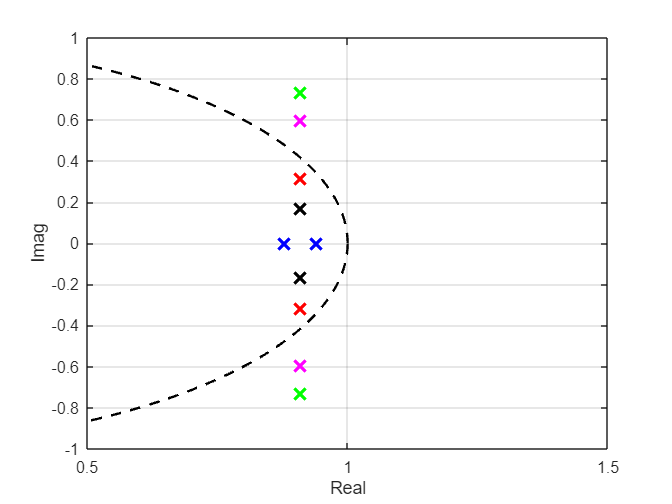

figure();
ang=0:0.01:2*pi; 
xp = cos(ang);
yp = sin(ang);
plot(xp, yp, '--k', 'LineWidth', 1.5);
grid on;
xlim([0.5, 1.5]);  xlabel('Real');
ylim([-1, 1]);  ylabel('Imag');

list_color = {'b', 'k', 'r', 'm', 'g'};

for idx = 1:length
    z = list_z{idx};
    for j = 1:2
        hold on;
        plot(real(z(j)), imag(z(j)), 'Marker', 'X', 'LineWidth', 2, 'MarkerSize', 10, 'MarkerEdgeColor', list_color{idx});
    end
end

여기서 

- $K = 0.2$ (파랑) : 실수축 위에 두 근이 모두 위치합니다.

- $K = 1$ (검정) & $K = 3$ (빨강) : 두 근의 허수부가 존재하며, 크기가 1보다 작습니다. (즉, 두 근 모두 단위원 안쪽에 위치합니다.)

- $K = 10$ (마젠타) & $K = 15$ (초록) : 두 근의 허수부가 존재하며, 크기가 1보다 큽니다. (즉, 두 근 모두 단위원 바깥쪽에 위치합니다.)

이제 `step `함수를 이용하여 모든 경우의 단위 계단 응답을 하나의 그림으로 그려봅시다. 

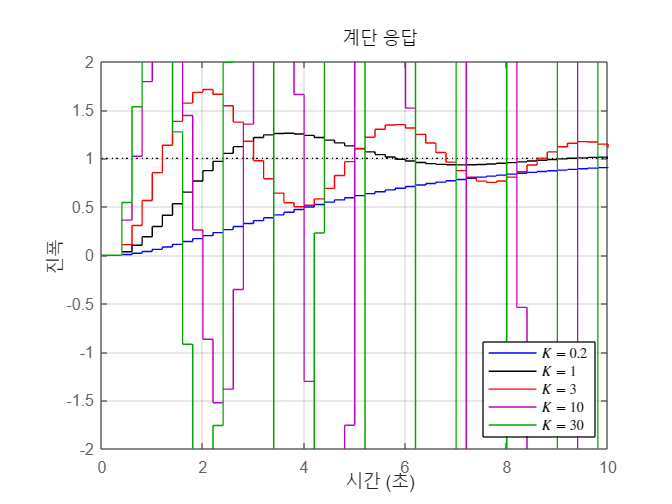

figure();
for idx = 1:length
    hold on;
    step(list_Td_tf{idx}, list_color{idx});
end
legend('$K=0.2$', '$K=1$', '$K = 3$', '$K = 10$', '$K = 15$','Interpreter','latex','Location','southeast');
grid on;
xlim([0 10]);
ylim([-2 2]);

위의 그림에서 각 경우에 대해 아래의 해석이 가능합니다.

- $K = 0.2$ (파랑) : 실수축 위에 두 근이 모두 위치하므로 oscillation 없이 정상상태값으로 수렴합니다.

- $K = 1$ (검정) & $K = 3$ (빨강) : 두 근의 허수부가 존재하므로 oscillation을 겪으면서 정상상태값으로 수렴합니다. 이 중 특성 방정식의 두 근이 단위원에 더 가까웠던 빨강색 경우의 응답 파형이 더 큰 oscillation을 겪음을 확인할 수 있습니다.

- $K = 10$ (마젠타) & $K = 15$ (초록) : 두 근의 크기가 1보다 크기 때문에 정상상태값으로 수렴하지 못하고 발산합니다. (이를 Chapter 7에서는 불안정성(instability)라고 부릅니다.)